# SIMPLE  K BANDIT

Nombre : Marco Esteban Aguirre Rojas

-  Develop a program in Matlab (using live scripts) that produces the same results shown in Figure 2.2. from the Book Reinforcement Learning by Sutton y Barto. 

"" Average performance of ε-greedy action-value methods on the 10-armed testbed. These data are averages over 2000 runs with different bandit problems. All methods used sample averages as their action-value estimates""

Nuemro de bandidos k = 10  , 2000 runs , N= 1000 pasos , E epsilon = 0 | 0,01| 0,1

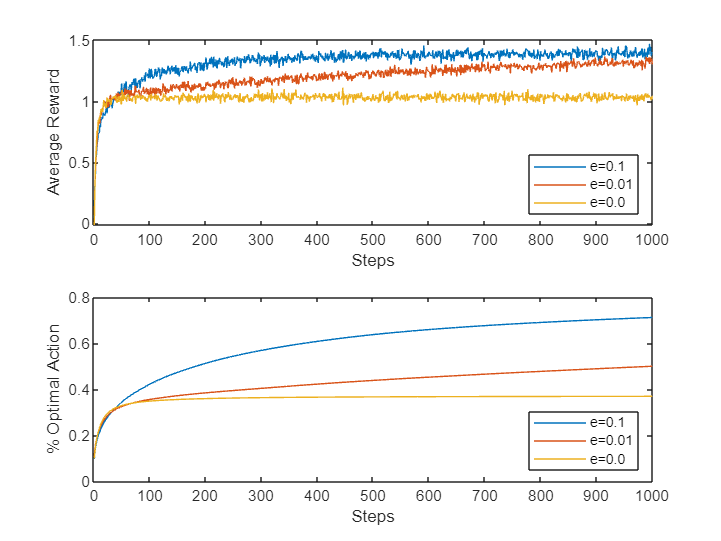

clc; clear all;
%mean_q_xa rewards were selected according to a mean q⇤(a)
Epsilons   = [0.1 , 0.01 , 0.0]; 
auxPlot    = zeros(1,1000);
vector_dim = (1:1000);
for epsilon = Epsilons
    optimal_m  = zeros(1,1000);
    Ravg       = zeros(1,1000);
    for j=1:2000
        mean_q_xa   = randn(10,1);
        [As,Q,R]    = simple_bandit(mean_q_xa,1000,epsilon);
        Ravg        = Ravg + R;
        [~,max_ind] =  max(mean_q_xa);
        optimal_m   =  optimal_m + cumsum(As == max_ind)./vector_dim;
    end
 %primera figura Average Reward
subplot(2,1,1);
Ravg=Ravg./2000;
plot(1:1000,Ravg);
xlabel('Steps');
ylabel('Average Reward');
legend('e=0.1','e=0.01','e=0.0','Location','southeast');
hold on;
%segunda figura Optimal Action
subplot(2,1,2);
plot(1:1000,optimal_m./2000 );
xlabel('Steps');
ylabel('% Optimal Action');
legend('e=0.1','e=0.01','e=0.0','Location','southeast');
hold on;
end